# Figure 1 G, H, I



defaultDir = 'F:\Calvin\tmem16a\IHC ISC Calcium imaging'
cd(defaultDir);


con1 = load('20201113 exp389 mouse 1 tectacre tmem16fl+ gc3 1x movie 4_IHCstruct.mat')
con2 = load('20210414 exp425 mouse 3 prep1 tec ta cre tmem16fl+ gc3 movie 1x_IHCstruct.mat')
con3 = load('20210414 exp425 mouse 3 prep2 tecta cre tmem16fl+ gc3 movie 1x_IHCstruct.mat')
con4 = load('20201022 exp380 tecta cre tmem16fl+ gcamp3 mouse 1 prep 1 10 min_IHCstruct.mat')
con5 = load('20201022 exp380 tecta cre tmem16fl+ gcamp3 mouse 2 prep 1 10 min_IHCstruct.mat')

cko1 = load('20210106 exp400 mouse 10 prep 2 tecta cre tmem16flfl gc3 movie 1_IHCstruct.mat')
cko2 = load('20201124 exp392 mouse 8 prep 1 tecta cre tmem16a gc3 1x_IHCstruct.mat')
cko3 = load('20210106 exp400 mouse 10 prep 1 tecta cre tmem16flfl gc3 movie 1_IHCstruct.mat')
cko4 = load('20210106 exp400 mouse 12 prep 1 tecta cre tmem16flfl gc3 movie 1_IHCstruct.mat')
cko5 = load('20210106 exp400 mouse 8 prep 1 tecta cre tmem16flfl gc3 movie 2_IHCstruct.mat')
cko6 = load('20201124 exp392 mouse 8 prep 2 tecta cre tmem16a gc3 movie 4 1x_IHCstruct.mat')

% calcium event properties
[con1freq con1amp con1dur] = IHCgroupProps(con1);
[con2freq con2amp con2dur] = IHCgroupProps(con2);
[con3freq con3amp con3dur] = IHCgroupProps(con3);
[con4freq con4amp con4dur] = IHCgroupProps(con4);
[con5freq con5amp con5dur] = IHCgroupProps(con5);

conFreq = [con1freq, con2freq,con3freq,con4freq,con5freq];

[cko1freq cko1amp cko1dur] = IHCgroupProps(cko1);
[cko2freq cko2amp cko2dur] = IHCgroupProps(cko2);
[cko3freq cko3amp cko3dur] = IHCgroupProps(cko3);
[cko4freq cko4amp cko4dur] = IHCgroupProps(cko4);
[cko5freq cko5amp cko5dur] = IHCgroupProps(cko5);
[cko6freq cko6amp cko6dur] = IHCgroupProps(cko6);

ckoFreq = [cko1freq,cko2freq,cko3freq,cko4freq,cko5freq,cko6freq];

conditions = {'Control','cKO'};
markSz = [20 20]
dim = [1 2];
ylbl = ('Events per minute');
[fig1 h p1] = compare2(conFreq,ckoFreq,conditions,ylbl,dim,markSz)
ylim([0 3]);

conAmp = [con1amp,con2amp,con3amp,con4amp,con5amp]*100;
ckoAmp = [cko1amp,cko2amp,cko3amp,cko4amp,cko5amp,cko6amp]*100;
conditions = {'Control','cKO'};
markSz = [20 20]
dim = [1 2];
ylbl = ('Mean amplitude (%dFoF)');
[fig2 h p2] = compare2(conAmp,ckoAmp,conditions,ylbl,dim,markSz)
ylim([0 150]);

conDur = [con1dur,con2dur,con3dur,con4dur,con5dur];
ckoDur = [cko1dur,cko2dur,cko3dur,cko4dur,cko5dur,cko6dur];
conditions = {'Control','cKO'};
markSz = [20 20]
dim = [1 2];
ylbl = ('Mean duration (s)');
[fig3 h p3] = compare2(conDur,ckoDur,conditions,ylbl,dim,markSz)
ylim([0 3]);

subP = handleTheSubplot({fig1,fig2,fig3},[1 3]);
figQuality(subP,gca,[3 2])

[CorrP CorrA h] = fdr_BH([p1,p2,p3],0.05)


% Rasters
[x,n] = size(con1.IHCstruct.roisignalNorm);
t = 1250;
numToShow = 20;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con1.IHCstruct.roisignalNorm(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[2.75 1])

[x,n] = size(cko1.IHCstruct.roisignalNorm);
t = 1250;
numToShow = 20;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(cko1.IHCstruct.roisignalNorm(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[2.75 1])


% Correlation matrix
ConCor1 = corr(con1.IHCstruct.roisignalNorm(:,1:47));
size(con1.IHCstruct.roisignalNorm)

ans =         1250          48


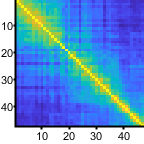

figure
imagesc(ConCor1)
figQuality(gcf,gca,[1.5 1.5])


ConCor2 = corr(con2.IHCstruct.roisignalNorm(:,1:47));
size(con2.IHCstruct.roisignalNorm)

ans =         1250          54


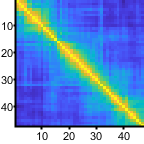

figure
imagesc(ConCor2)
figQuality(gcf,gca,[1.5 1.5])


ConCor3 = corr(con3.IHCstruct.roisignalNorm(:,1:47));
size(con3.IHCstruct.roisignalNorm)

ans =         1250          52


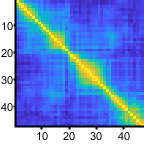

figure
imagesc(ConCor3)
figQuality(gcf,gca,[1.5 1.5])


ConCor4 = corr(con4.IHCstruct.roisignalNorm(:,1:47));
size(con4.IHCstruct.roisignalNorm)

ans =         1250          47


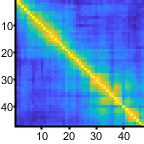

figure
imagesc(ConCor4)
figQuality(gcf,gca,[1.5 1.5])


ConCor5 = corr(con5.IHCstruct.roisignalNorm(:,1:47));
size(con5.IHCstruct.roisignalNorm)

ans =         1250          65


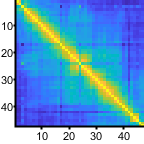

figure
imagesc(ConCor5)
figQuality(gcf,gca,[1.5 1.5])


% mean correlation matrix
conMeanCorr = (ConCor1+ConCor2+ConCor3+ConCor4+ConCor5)/5

conMeanCorr =     1.0000    0.7754    0.6032    0.5168    0.4410    0.3842    0.3113    0.2838    0.2548    0.2443    0.2301    0.2277    0.1887    0.1607    0.1448    0.0960    0.1049    0.0589    0.0820    0.0673    0.0521    0.0336    0.0486    0.0148    0.0445    0.0612    0.0342    0.0415    0.0185    0.0319    0.0494    0.0317    0.0065    0.0161    0.0234    0.0058    0.0139    0.0155    0.0099   -0.0172    0.0044   -0.0061   -0.0075   -0.0400   -0.0146   -0.0039   -0.0131
    0.7754    1.0000    0.7078    0.6496    0.5498    0.4942    0.4354    0.3613    0.3379    0.3013    0.2909    0.3013    0.2522    0.2233    0.1968    0.1755    0.1853    0.1288    0.1210    0.1194    0.0860    0.0706    0.0754    0.0205    0.0682    0.0830    0.0316    0.0372    0.0109    0.0214    0.0541    0.0407    0.0133    0.0170    0.0312    0.0145    0.0240    0.0207    0.0195   -0.0047    0.0047    0.0020   -0.0118   -0.0342   -0.0186   -0.0058   -0.0177
    0.6032    0.7078    1.0000    0.7201    

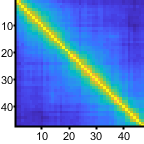

figure;
imagesc(conMeanCorr)
figQuality(gcf,gca,[1.5 1.5])


ckoCor1 = corr(cko1.IHCstruct.roisignalNorm(:,1:47));
size(cko1.IHCstruct.roisignalNorm)

ans =         1250          52


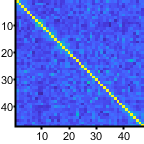

imagesc(ckoCor1)
figQuality(gcf,gca,[1.5 1.5])


ckoCor2 = corr(cko2.IHCstruct.roisignalNorm(:,1:47));
size(cko2.IHCstruct.roisignalNorm)

ans =         1250          60


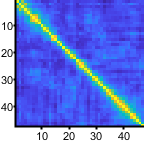

imagesc(ckoCor2)
figQuality(gcf,gca,[1.5 1.5])


ckoCor3 = corr(cko3.IHCstruct.roisignalNorm(:,1:47));
size(cko3.IHCstruct.roisignalNorm)

ans =         1250          56


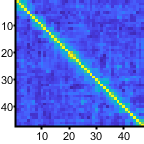

imagesc(ckoCor3)
figQuality(gcf,gca,[1.5 1.5])


ckoCor4 = corr(cko4.IHCstruct.roisignalNorm(:,1:47));
size(cko4.IHCstruct.roisignalNorm)

ans =         1250          59


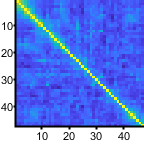

imagesc(ckoCor4)
figQuality(gcf,gca,[1.5 1.5])


ckoCor5 = corr(cko5.IHCstruct.roisignalNorm(:,1:47));
size(cko5.IHCstruct.roisignalNorm)

ans =         1250          56


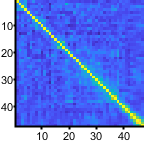

imagesc(ckoCor5)
figQuality(gcf,gca,[1.5 1.5])


ckoCor6 = corr(cko6.IHCstruct.roisignalNorm(:,1:47));
size(cko6.IHCstruct.roisignalNorm)

ans =         1250          55


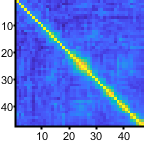

imagesc(ckoCor6)
figQuality(gcf,gca,[1.5 1.5])


% mean correlation matrix

ckoMeanCorr = (ckoCor1+ckoCor2+ckoCor3+ckoCor4+ckoCor5+ckoCor6)/6

ckoMeanCorr =     1.0000    0.3551    0.3251    0.2692    0.1016    0.0828    0.0519    0.0264   -0.0052   -0.0112   -0.0285   -0.0439   -0.0129    0.0078    0.0204    0.0083   -0.0020   -0.0030   -0.0242    0.0162    0.0083   -0.0231    0.0277   -0.0426   -0.0235    0.0008    0.0237    0.0043   -0.0108    0.0127   -0.0191   -0.0180   -0.0369   -0.0046    0.0031   -0.0168    0.0134   -0.0165    0.0236    0.0354    0.0061    0.0222    0.0276    0.0181   -0.0070    0.0017    0.0080
    0.3551    1.0000    0.3657    0.3454    0.1466    0.1386    0.0466    0.0566    0.0958    0.0602   -0.0053   -0.0200   -0.0166    0.0167    0.0291    0.0205    0.0358   -0.0240    0.0553    0.0201    0.0227    0.0130    0.0371    0.0277    0.0169    0.0482    0.0527    0.0522    0.0065    0.0242    0.0405    0.0193   -0.0217    0.0040   -0.0083   -0.0322   -0.0118    0.0035   -0.0014    0.0338    0.0269    0.0387    0.0403    0.0237    0.0230   -0.0048    0.0052
    0.3251    0.3657    1.0000    0.3654    

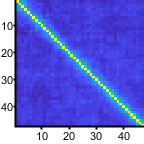

figure;
imagesc(ckoMeanCorr)
figQuality(gcf,gca,[1.5 1.5])



% 80th percentile correlation coefficient 

ConCor1 = corr(con1.IHCstruct.roisignalNorm(:,:));
meanConCor1 = prctile(ConCor1,80,'all'); 
ConCor2 = corr(con2.IHCstruct.roisignalNorm(:,:));
meanConCor2 = prctile(ConCor2,80,'all'); 
ConCor3 = corr(con3.IHCstruct.roisignalNorm(:,:));
meanConCor3 = prctile(ConCor3,80,'all'); 
ConCor4 = corr(con4.IHCstruct.roisignalNorm(:,:));
meanConCor4 = prctile(ConCor4,80,'all'); 
ConCor5 = corr(con5.IHCstruct.roisignalNorm(:,:));
meanConCor5 = prctile(ConCor5,80,'all'); 

CkoCor1 = corr(cko1.IHCstruct.roisignalNorm(:,:));
meanCkoCor1 = prctile(CkoCor1,80,'all'); 
CkoCor2 = corr(cko2.IHCstruct.roisignalNorm(:,:));
meanCkoCor2 = prctile(CkoCor2,80,'all'); 
CkoCor3 = corr(cko3.IHCstruct.roisignalNorm(:,:));
meanCkoCor3 = prctile(CkoCor3,80,'all'); 
CkoCor4 = corr(cko4.IHCstruct.roisignalNorm(:,:));
meanCkoCor4 = prctile(CkoCor4,80,'all'); 
CkoCor5 = corr(cko5.IHCstruct.roisignalNorm(:,:));
meanCkoCor5 = prctile(CkoCor5,80,'all'); 
CkoCor6 = corr(cko6.IHCstruct.roisignalNorm(:,:));
meanCkoCor6 = prctile(CkoCor6,80,'all'); 


conCor = [meanConCor1,meanConCor2,meanConCor3,meanConCor4,meanConCor5]

conCor =     0.4550    0.4171    0.3454    0.4750    0.3613


CkoCor = [meanCkoCor1,meanCkoCor2,meanCkoCor3,meanCkoCor4,meanCkoCor5,meanCkoCor6]

CkoCor =     0.0934    0.1244    0.1141    0.1158    0.0985    0.1241



ylbl1 = 'Mean correlation coefficient';
[fig5 h p5] = compare2(conCor,CkoCor,conditions,ylbl1,dim);

not normal

p5

p5 = 0.0043

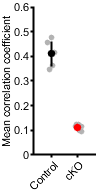

ylim([0 0.6])


subP = handleTheSubplot({fig1,fig2,fig5},[1 3]);

Invalid or deleted object.

Error in handleTheSubplot (line 16)
        axhandles{i} = copyobj(handles{i}.Children,figh);

figQuality(subP,gca,[3 2])

[CorrP CorrA h] = fdr_BH([p1,p2,p5],0.05)